clc
clear
close all
rng('default');

set(0, 'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 14)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## Generate data, genero un AR(3)

me = 3; % mean of the white noise
N = 11000; % number of data
e = randn(N, 1) + me; % generate WN vector
y = zeros(length(e), 1); % initialize output vector
y_rec = zeros(length(e), 1); % initialize output vector computed with explicit recursive form
Ts = 0.02; % sample time [s] (tempo di campionamento)
fs = 1/Ts; % sampling frequency [Hz]
time = 0:Ts:(N*Ts)-Ts;

% Transfer function of the process
a = [0.7 -0.2 -0.3]; % coefficients of the AR part
Hz = tf([1 0 0 0], [1 -a] ,'Ts', Ts, 'variable', 'z^-1');
Hz

Hz =
 
                  1
  ----------------------------------
  1 - 0.7 z^-1 + 0.2 z^-2 + 0.3 z^-3
 
Sample time: 0.02 seconds
Discrete-time transfer function.




% Is H(z) asymptotically stable?
% Abs value of the poles of the transfer function
abs( pole(Hz) ) %poli della funzione

ans =     0.8317
    0.8317
    0.4337


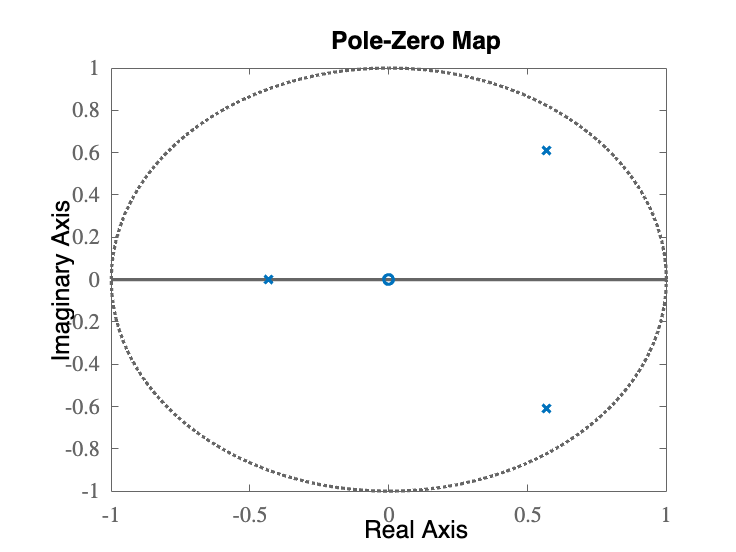


% Plot poles/zero on the unit circle
figure;
iopzmap(Hz); %Disegna il cerchio unitario
set(findall(gcf, 'type', 'line'), 'linewidth', 2);

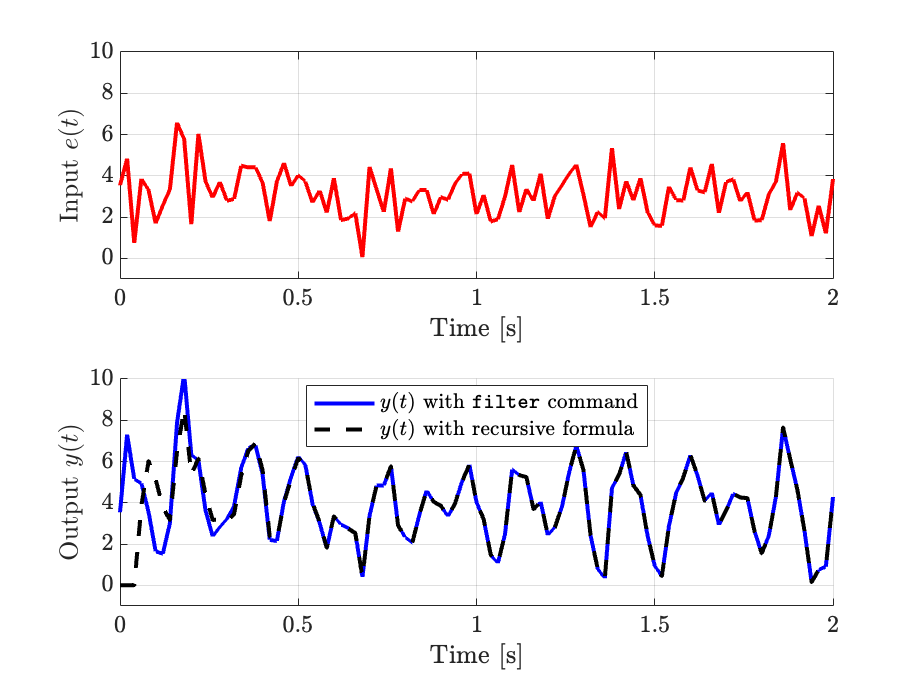




C = cell2mat(Hz.Numerator); % coefficients numerator
A = cell2mat(Hz.Denominator); % coefficients denominator

%Genero l'uscita
for t = 4 : 1: N % generate output data with recursive formula
    y_rec(t) = a(1)*y_rec(t-1) + a(2)*y_rec(t-2) + a(3)*y_rec(t-3) + e(t);
end

y = filter(C, A, e); % generate output data with filter command

figure;
h1 = subplot(211);
plot(time, e, 'r');
xlim([0, 2]);
ylim([-1, 10]);
xlabel('Time [s]', 'interpreter', 'latex'); ylabel('Input $e(t)$', 'interpreter', 'latex');  grid on
h2 = subplot(212);
hold all;
plot(time, y, 'b');
plot(time, y_rec, 'k--');
legend('$y(t)$ with $\texttt{filter}$ command', '$y(t)$ with recursive formula', 'location', 'best');
xlim([0, 2]);
ylim([-1, 10]);
xlabel('Time [s]', 'interpreter', 'latex'); ylabel('Output $y(t)$', 'interpreter', 'latex');  grid on
linkaxes([h1, h2]);

## Pre-process data

% Remove initial condition to obtain a stationary process
% I dati sono lunghi 10k al posto di 11k
Ninit = 1000;
y = y(Ninit+1:end);
e = e(Ninit+1:end);
N = N - Ninit;
time = 0:Ts:(N*Ts)-Ts;

## Estimate the expected value of y(t)

theoretical_mean = me/(1 - a(1) - a(2) - a(3)) % theoretical mean

theoretical_mean = 3.7500

my = mean(y) % sample (temporal) estimate of the expected value of y(t)

my = 3.7569

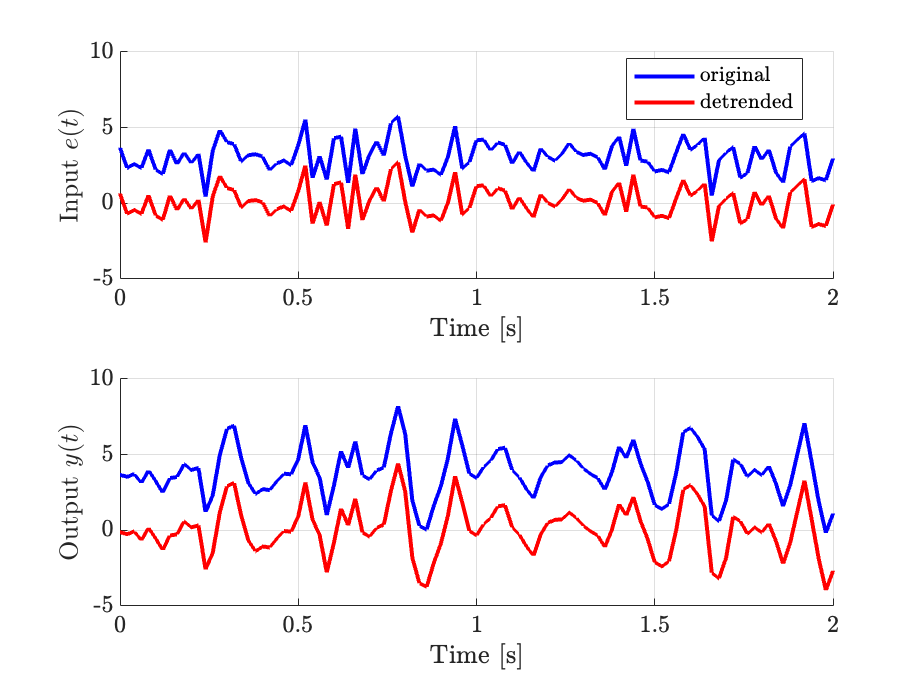


% let's assume to work with zero mean signals
% Toglie i trend dai dataset
yd = detrend(y);
ed = detrend(e);


figure;
h1 = subplot(211);
hold all;
plot(time, e, 'b');
plot(time, ed, 'r');
xlim([0, 2]);
legend('original', 'detrended', 'location', 'best');
xlabel('Time [s]', 'interpreter', 'latex'); ylabel('Input $e(t)$', 'interpreter', 'latex');  grid on
h2 = subplot(212);
hold all;
plot(time, y, 'b');
plot(time, yd, 'r');
xlim([0, 2]);
xlabel('Time [s]', 'interpreter', 'latex'); ylabel('Output $y(t)$', 'interpreter', 'latex');  grid on
linkaxes([h1, h2]);

## Estimate the autocovariance function of y(t)

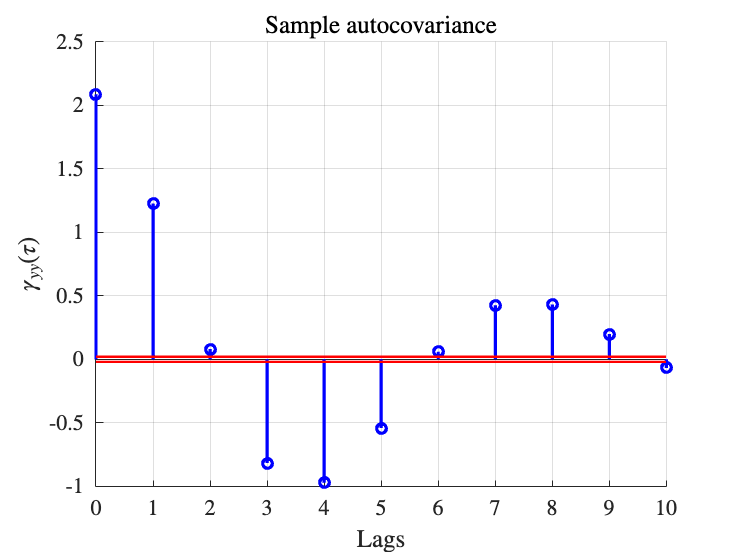

lags = 10; % lags up to which compute the estimated autocovariance function
[Ryy_hat, ~, bounds] = autocorr(y, lags); % sample autocorrelation function
% - bounds contains the 95% confidence intervals on the estimate

gammayy_hat_0 = var(y); % variance of y(t)
gammayy_hat = gammayy_hat_0 * Ryy_hat; % autocovariance function

figure
hold on
stem(0:1:lags, gammayy_hat, 'b', 'linewidth', 2);
l = line([0 lags], [bounds(1) bounds(1)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
l = line([0 lags], [bounds(2) bounds(2)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
grid on; xlabel('Lags', 'interpreter', 'latex');  ylabel('$\gamma_{yy}(\tau)$', 'interpreter', 'latex')
title('Sample autocovariance', 'interpreter', 'latex');
xticks(0:1:lags);

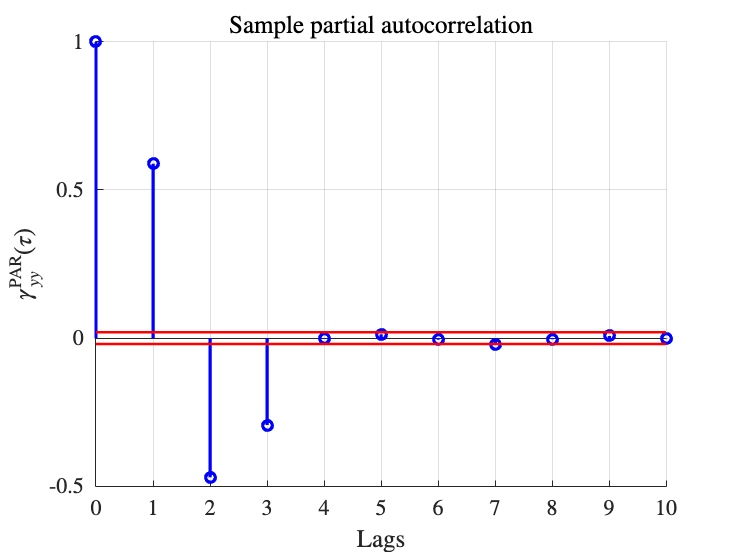




% Partial autocorrelation function
[gammayy_PAR_hat, ~, bounds] = parcorr(y, lags);

figure
hold on
stem(0:1:lags, gammayy_PAR_hat, 'b', 'linewidth', 2);
l = line([0 lags], [bounds(1) bounds(1)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
l = line([0 lags], [bounds(2) bounds(2)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
grid on; xlabel('Lags', 'interpreter', 'latex'); ylabel('$\gamma^\textrm{PAR}_{yy}(\tau)$', 'interpreter', 'latex')
title('Sample partial autocorrelation', 'interpreter', 'latex');
xticks(0:1:lags);

## Compute the power spectral density

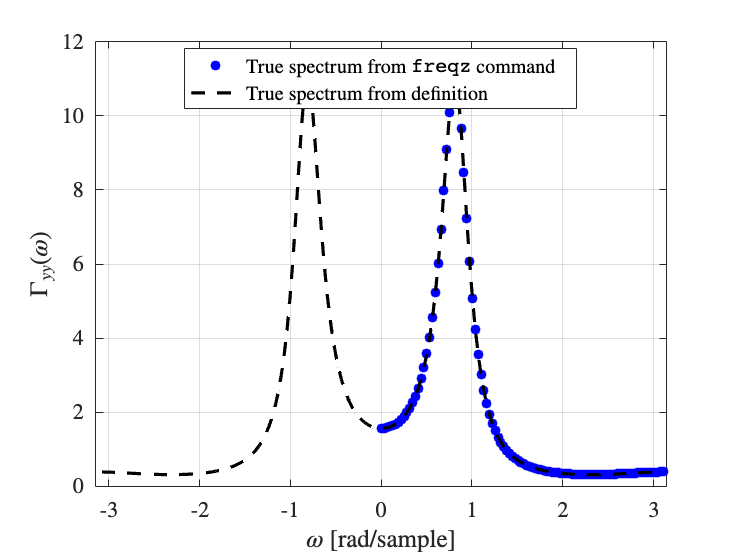

num_frequencies = 100;  % points onto which to evaluate the frequency response
[Hz_frf, w_norm_eval] = freqz(C, A, num_frequencies); % frequency response of H(z)
Hz_frf_mag = abs(Hz_frf).^2; % squared modulus of the frequency response


% Compute power spectral density using the definition
Gamma_ee = 1; % psd of the white noise (its variance)
w_norm = -3*pi:pi/num_frequencies:3*pi; % normalized pulsations where compute the spectrum
Gamma_yy = 1./abs(1 - a(1)*exp(1j*w_norm) - a(2)*exp(2*1j*w_norm) - a(3)*exp(3*1j*w_norm) ).^2 * Gamma_ee;


figure
plot(w_norm_eval, Hz_frf_mag, 'b*', 'linewidth', 2)
hold on;
plot(w_norm, Gamma_yy, 'k--' ,'linewidth', 2); grid on; xlim([-pi, pi]);
xlabel('$\omega$ [rad/sample]', 'interpreter', 'latex'); ylabel('$\Gamma_{yy}(\omega)$', 'interpreter', 'latex');
legend('True spectrum from $\texttt{freqz}$ command', 'True spectrum from definition', 'Location', 'best')

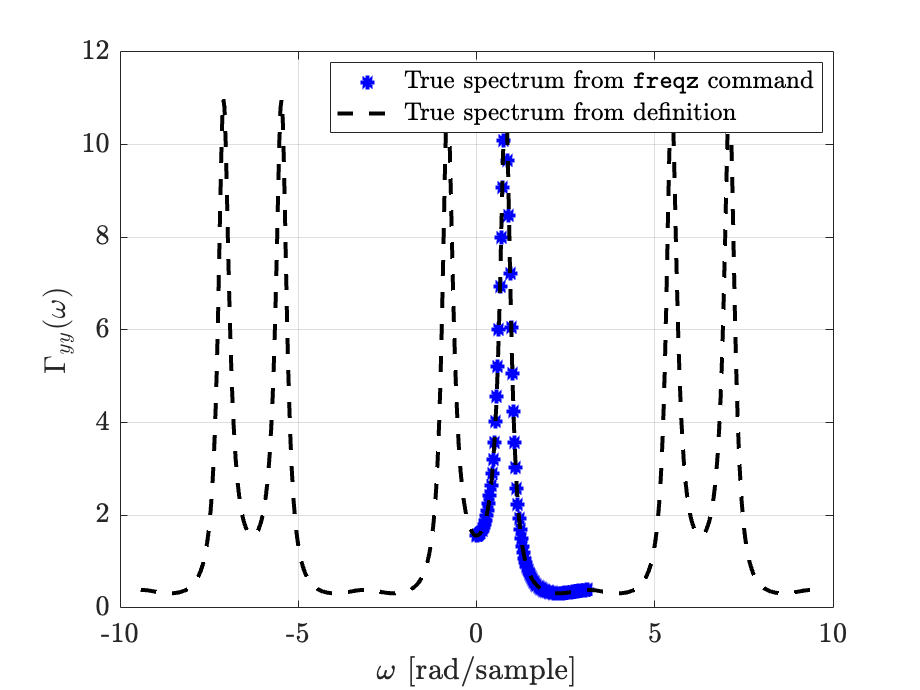



% Just to show that the psd is symmetric and periodic
figure
plot(w_norm_eval, Hz_frf_mag, 'b*', 'linewidth', 2)
hold on;
plot(w_norm, Gamma_yy, 'k--' ,'linewidth', 2); grid on;
xlabel('$\omega$ [rad/sample]', 'interpreter', 'latex'); ylabel('$\Gamma_{yy}(\omega)$', 'interpreter', 'latex');
legend('True spectrum from $\texttt{freqz}$ command', 'True spectrum from definition', 'Location', 'best')

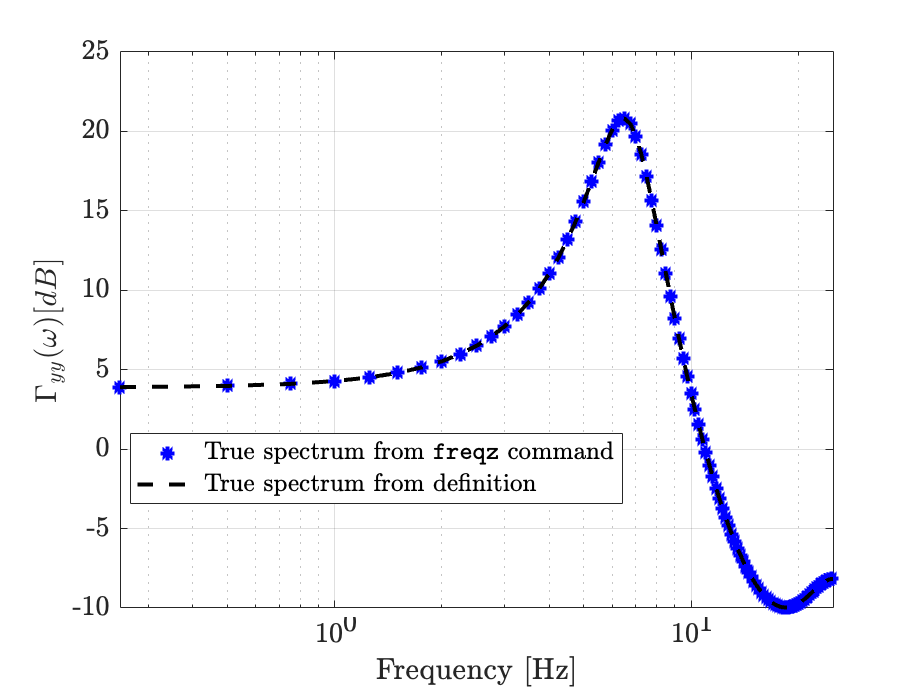



% If you want to display using real frequencies instead of normalized
% pulsations \omega
[Hz_frf, freq_eval] = freqz(C, A, num_frequencies, fs); % frequency response of H(z)
Hz_frf_mag = abs(Hz_frf).^2; % squared modulus of the frequency response

w_norm = -pi:pi/num_frequencies:pi; % normalized pulsations where compute the spectrum
Gamma_yy = 1./abs(1 - a(1)*exp(1j*w_norm) - a(2)*exp(2*1j*w_norm) - a(3)*exp(3*1j*w_norm) ).^2 * Gamma_ee;

figure
semilogx(freq_eval, db(Hz_frf_mag), 'b*', 'linewidth', 2)
hold on;
semilogx(w_norm*fs/(2*pi), db(Gamma_yy), 'k--' ,'linewidth', 2); grid on;
xlim([0, fs/2]);
xlabel('Frequency [Hz]', 'interpreter', 'latex'); ylabel('$\Gamma_{yy}(\omega) [dB]$', 'interpreter', 'latex');
legend('True spectrum from $\texttt{freqz}$ command', 'True spectrum from definition', 'Location', 'best')




%  Same results can be obtained witht the Bode command
[mag, ~] = bode(Hz, freq_eval*2*pi)

mag = mag(:,:,1) =

    1.2500


mag(:,:,2) =

    1.2518


mag(:,:,3) =

    1.2573


mag(:,:,4) =

    1.2665


mag(:,:,5) =

    1.2795


mag(:,:,6) =

    1.2966


mag(:,:,7) =

    1.3180


mag(:,:,8) =

    1.3440


mag(:,:,9) =

    1.3751


mag(:,:,10) =

    1.4116


mag(:,:,11) =

    1.4543


mag(:,:,12) =

    1.5037


mag(:,:,13) =

    1.5609


mag(:,:,14) =

    1.6268


mag(:,:,15) =

    1.7027


mag(:,:,16) =

    1.7899


mag(:,:,17) =

    1.8901


mag(:,:,18) =

    2.0050


mag(:,:,19) =

    2.1362


mag(:,:,20) =

    2.2851


mag(:,:,21) =

    2.4519


mag(:,:,22) =

    2.6344


mag(:,:,23) =

    2.8262


mag(:,:,24) =

    3.0142


mag(:,:,25) =

    3.1766


mag(:,:,26) =

    3.2853


mag(:,:,27) =

    3.3140


mag(:,:,28) =

    3.2511


mag(:,:,29) =

    3.1071


mag(:,:,30) =

    2.9088


mag(:,:,31) =

    2.6861


mag(:,:,32) =

    2.4621


mag(:,:,33) =

    2.2510


mag(:,:,34) =

    2.0592


mag(:,:,35) =

    1.8886


mag(:,:,36) =

    1.73

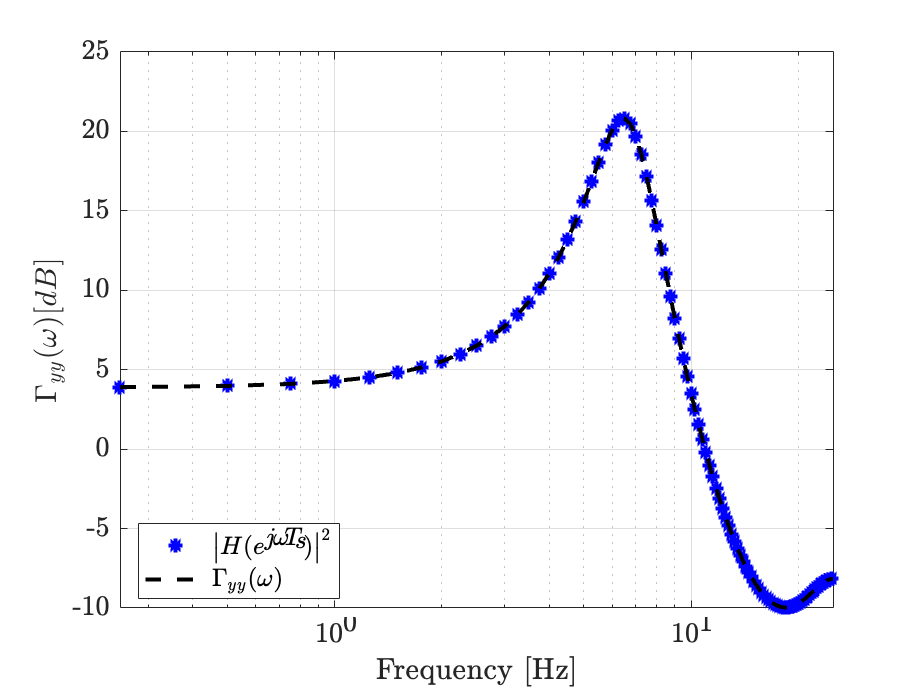

modhat = squeeze(mag);

figure
semilogx(freq_eval, db(modhat.^2), 'b*', 'linewidth', 2);
hold on;
semilogx(w_norm*fs/(2*pi), db(Gamma_yy), 'k--' ,'linewidth', 2); grid on;
xlim([0, fs/2]);
xlabel('Frequency [Hz]', 'interpreter', 'latex'); ylabel('$\Gamma_{yy}(\omega) [dB]$', 'interpreter', 'latex');
legend('$\left\vert H(e^{j \omega T_s})\right\vert^2$', '$\Gamma_{yy}(\omega)$', 'Location', 'best')

## Estimate the power spectral density

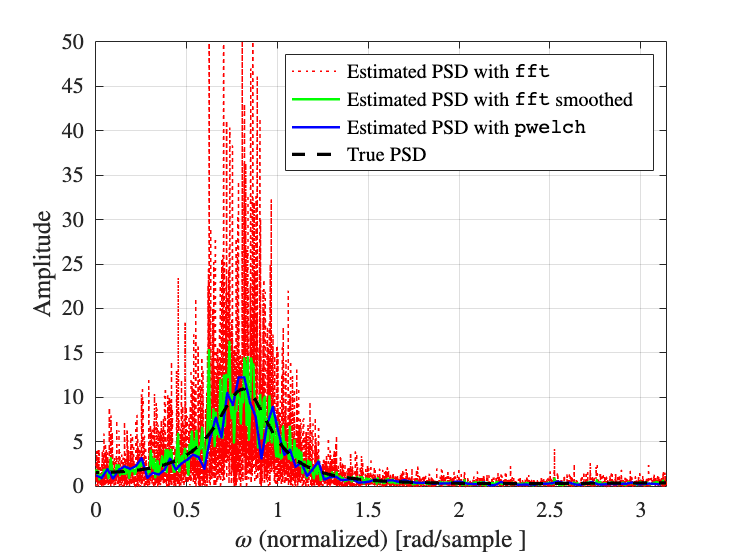

% Estimation with the fft
bin = fs/N; % frequency resolution of the fft
freqs = [0 bin:bin:(N/2-1)*bin]; % grid of discrete frequencies

% Gamma_yy_hat_fft = 1/N * fft(yd) .* conj( fft(yd) );
Gamma_yy_hat_fft = 1/N * abs(fft(yd)).^2; % alternative command
Gamma_yy_hat_fft_useful = Gamma_yy_hat_fft(1:floor(N/2)); % retain only useful data from the fft


% Smoothed periodogram (10 folds with 1000 elements each)
n_folds = 10;               % folds number % 100 - 200
M = round(N/n_folds);        % elements in each fold
bin_smooth = fs/M;           % frequency resolution for smoothed periodogram
freqs_smooth = [0 bin_smooth:bin_smooth:(M/2-1)*bin_smooth]; % grid of discrete frequencies for smoothed periodogram

Gamma_yy_hat_temp = zeros(M, n_folds);
for k = 1 : n_folds
    temp = fft(yd(1+(k-1)*M:M+(k-1)*M));
    Gamma_yy_hat_temp(:, k) = abs(temp).^2 / M;
end
Gamma_yy_hat_smooth = mean(Gamma_yy_hat_temp, 2);  % estimate as the mean of the single spectra
Gamma_yy_hat_smooth_useful = Gamma_yy_hat_smooth(1:floor(M/2));



% Estimation with pwelch
WINDOW = []; % 100 - 200
Gamma_yy_hat_pwelch = pwelch(yd, WINDOW, [], w_norm_eval);
Gamma_yy_hat_pwelch = 2*pi * Gamma_yy_hat_pwelch; % the pwelch method returns a scaled psd, see documentation at https://it.mathworks.com/help/signal/ref/pwelch.html


figure;
plot(freqs/fs*2*pi, Gamma_yy_hat_fft_useful, 'r:', 'linewidth', 1);
hold on
plot(freqs_smooth/fs*2*pi, Gamma_yy_hat_smooth_useful, 'g', 'linewidth', 1.5);
plot(w_norm_eval, Gamma_yy_hat_pwelch , 'b', 'linewidth', 1.5);
plot(w_norm, Gamma_yy, 'k--');
xlabel('$\omega$ (normalized) [rad/sample ]', 'interpreter', 'latex'); ylabel('Amplitude', 'interpreter', 'latex');
grid on;
xlim([0, pi]);
ylim([0, 50]);
legend('Estimated PSD with $\texttt{fft}$', ...
    'Estimated PSD with $\texttt{fft}$ smoothed', ...
    'Estimated PSD with $\texttt{pwelch}$', ...
    'True PSD');

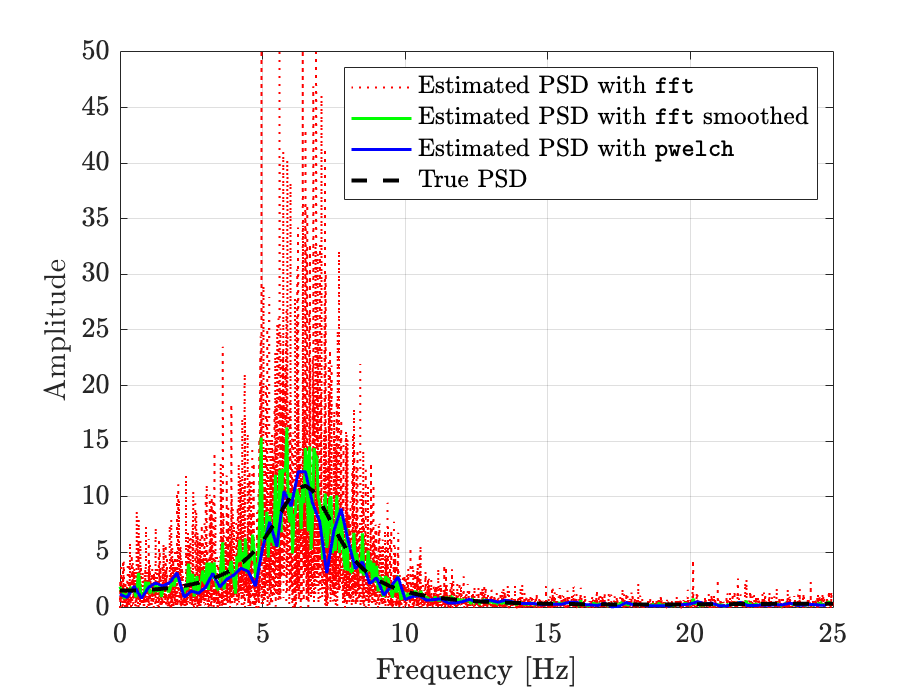



figure;
plot(freqs, Gamma_yy_hat_fft_useful, 'r:', 'linewidth', 1);
hold on
plot(freqs_smooth, Gamma_yy_hat_smooth_useful, 'g', 'linewidth', 1.5);
plot(w_norm_eval*fs/(2*pi), Gamma_yy_hat_pwelch , 'b', 'linewidth', 1.5);
plot(w_norm*fs/(2*pi), Gamma_yy, 'k--');
xlabel('Frequency [Hz]', 'interpreter', 'latex'); ylabel('Amplitude', 'interpreter', 'latex');
grid on;
xlim([0, fs/2]);
ylim([0, 50]);
legend('Estimated PSD with $\texttt{fft}$', ...
    'Estimated PSD with $\texttt{fft}$ smoothed', ...
    'Estimated PSD with $\texttt{pwelch}$', ...
    'True PSD');